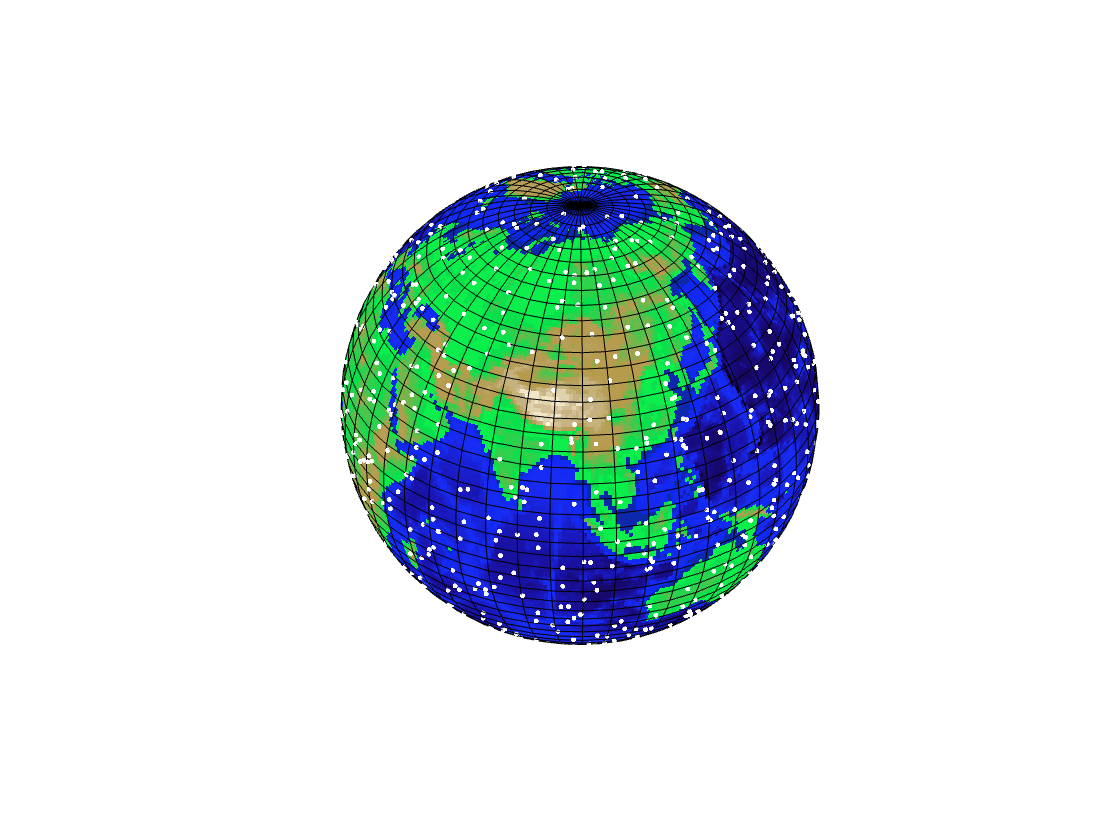

cla reset;
load topo;
[x y z] = sphere(45);
s = surface(x,y,z,'FaceColor','texturemap','CData',topo);
 colormap(topomap1);
campos([1.3239  -14.4250  9.4954]);
axis off vis3d;
x = [0.7698 0.5851];
 y = [0.3593 0.5492];
hold on

axis equal
a = zeros(1000,3);
for i = 1:1000
    u = 2*rand - 1;
    theta = 2*pi*rand;
    x = sqrt(1-u^2) * cos(theta);
    y = sqrt(1-u^2) * sin(theta);
    z = u;
    a(i,1) = x;
    a(i,2) = y;
    a(i,3) = z;
    plot3(x,y,z,'.','Color','white'); 
end